# Compare eBird and KBM coverage

- Filter checklists: in Africa, exclude historical without time and distance

- Assign pentad code (e.g., 0020c3650) to each checklist based on the checklist location

- Filter (traveling) checklists overlapping two pentads. Either trace or center + distance traveled

- Group checklists by observer, pentad, day. Get  list of species, sum duration 

- Group by card (5 rolling days). This step is a bit more tricky and language dependant I guess. We might have to loop through the unique observer-pentad, sort by day, check if valid protocol (>2hr in the next 5 days), and finally group by 5 days

addpath('functions/')

## Process eBird **checklist** data

Combine to the checklist level

if false
    for cntr = ["KE", "ZA", "NG", "NA"]
        ebd0 = readtable("data/eBird/ebd_"+cntr+"_relAug-2022/ebd_"+cntr+"_relAug-2022.txt",TextType="string");
        
        % Keep only important variable
        ebd = groupsummary(ebd0,["SAMPLINGEVENTIDENTIFIER","LATITUDE","LONGITUDE","OBSERVATIONDATE","PROTOCOLTYPE","DURATIONMINUTES","EFFORTDISTANCEKM","ALLSPECIESREPORTED","OBSERVERID"]);
        ebd = sortrows(ebd,"OBSERVATIONDATE");

        % Assign to pentad and check if distance remains inside
        ebd.PENTAD = latlon2pentad(ebd.LATITUDE, ebd.LONGITUDE);
        %Search center of pentad
        [lat,lon] = pentad2latlng(ebd.PENTAD);
        % ebd.distcenter = deg2km(distance(ebd.LATITUDE, ebd.LONGITUDE, lat, lon));
        % Filter distance
        ebd.KEEP_PENTAD = ~(km2deg(ebd.EFFORTDISTANCEKM)+max(abs(lat-ebd.LATITUDE), abs(lon-ebd.LONGITUDE))>5/60/2);
        save("data/eBird/ebd_"+cntr+".mat","ebd");
    end
end

Download KBM coverage

websave("data/kbm/coverage_KE.geojson","https://api.birdmap.africa/sabap2/v2/coverage/project/kenya?format=geoJSON", weboptions("Timeout",60))
websave("data/kbm/coverage_NA.geojson","https://api.birdmap.africa/sabap2/v2/coverage/project/namibia?format=geoJSON", weboptions("Timeout",60))
websave("data/kbm/coverage_ZA.geojson","https://api.birdmap.africa/sabap2/v2/coverage/project/sabap2?period=&format=geoJSON", weboptions("Timeout",60))

## Load data

cntr = "KE";
load("data/eBird/ebd_"+cntr+".mat");
abm = jsondecode(fileread(("data/kbm/coverage_"+cntr+".geojson")));

## Define country level pentad grid

extend=nan(2,2);
for i_f = 1:numel(abm.features)
    extend(1,1) = min(extend(1,1), min(abm.features(i_f).geometry.coordinates(:,:,:,1)), "omitnan");
    extend(1,2) = min(extend(1,2), min(abm.features(i_f).geometry.coordinates(:,:,:,2)), "omitnan");
    extend(2,1) = max(extend(2,1), max(abm.features(i_f).geometry.coordinates(:,:,:,1)), "omitnan");
    extend(2,2) = max(extend(2,2), max(abm.features(i_f).geometry.coordinates(:,:,:,2)), "omitnan");
end
extend(1,1) = floor(min(extend(1,1),min(ebd.LONGITUDE)));
extend(1,2) = floor(min(extend(1,2),min(ebd.LATITUDE)));
extend(2,1) = ceil(max(extend(2,1),max(ebd.LONGITUDE)));
extend(2,2) = ceil(max(extend(2,2),max(ebd.LATITUDE)));
g.res = 5 / 60;
g.lon = (extend(1,1)-g.res/2):g.res:(extend(2,1)+g.res/2);
g.lat = (extend(1,2)-g.res/2):g.res:(extend(2,2)+g.res/2);
[g.LAT,g.LON] = meshgrid(g.lat,g.lon);

compute pentad code

g.pentad = latlon2pentad(g.LAT, g.LON);

cell-centered

g.lon = g.lon + g.res/2;
g.lat = g.lat + g.res/2;
[g.LAT,g.LON] = meshgrid(g.lat,g.lon);

KBM coverage

fullProtocol = zeros(numel(g.lat), numel(g.lon));

ans = 1×3 table
    Total    Complete/Full    Total year
    _____    _____________    __________

    88743        53375          15.23   


fullProtocol_total_hours = zeros(numel(g.lat), numel(g.lon));
adhocProtocol = zeros(numel(g.lat), numel(g.lon));

ans = 1×3 table
    Total    Complete/Full    Total year
    _____    _____________    __________

    35195        10935          4.1463  


ans = 0.5292

for i_f = 1:numel(abm.features)
    id = strcmpi(abm.features(i_f).properties.pentad, g.pentad);
    assert(sum(id(:))>0)
    [i1,i2]=ind2sub(size(id),find(id));
    fullProtocol(i2,i1) = abm.features(i_f).properties.fullProtocol;
    fullProtocol_total_hours(i2,i1) = abm.features(i_f).properties.fullProtocol_total_hours;
    adhocProtocol(i2,i1) = abm.features(i_f).properties.adhocProtocol;
end

eBird

table(height(ebd),sum(ebd.ALLSPECIESREPORTED),nansum(ebd.DURATIONMINUTES)/60/24/365,VariableNames=["Total", "Complete/Full","Total year"])

ABM

table(sum(fullProtocol(:))+sum(adhocProtocol(:)),sum(fullProtocol(:)),sum(fullProtocol_total_hours(:))/24/365,VariableNames=["Total", "Complete/Full","Total year"])

ans = 12

mean(ebd.KEEP_PENTAD(ebd.ALLSPECIESREPORTED==1))

H-index of time

eBirdComplete = zeros(numel(g.lon), numel(g.lat));

ans = 16

eBirdTime=zeros(numel(g.lon), numel(g.lat));

ans = 8×4 table
                 PROTOCOLTYPE                 GroupCount    mean_KEEP_PENTAD    mean_ALLSPECIESREPORTED
    ______________________________________    __________    ________________    _______________________

    "Area"                                         48                 1                  0.6875        
    "Banding"                                       1                 1                       1        
    "Historical"                                 6327           0.92698                  0.4201        
    "Incidental"                                10598                 1                0.071429        
    "International Shorebird Survey (ISS)"          1                 1                       1        
    "Stationary"                                 6015                 1                 0.85536        
    "Traveling"

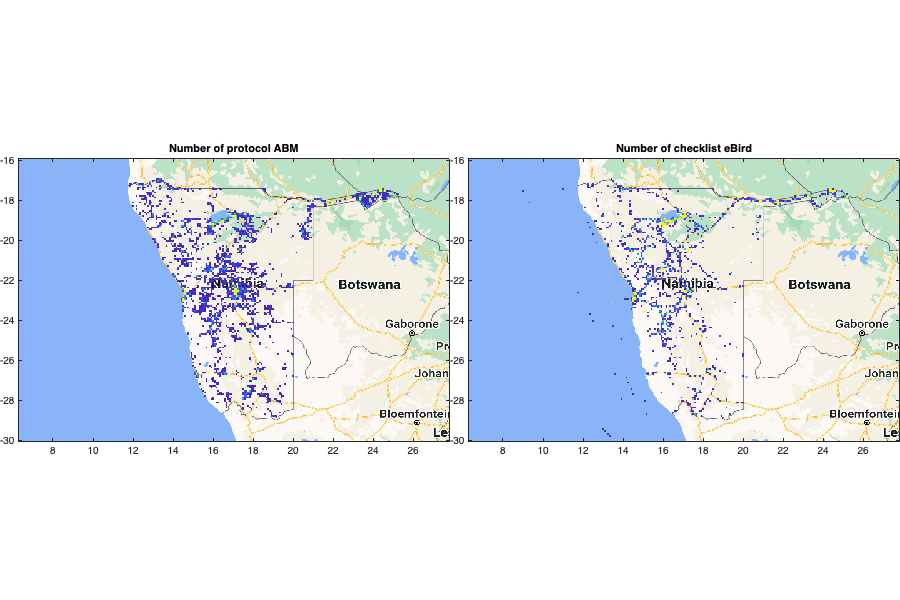

tmp = groupsummary(ebd,"PENTAD","sum",["ALLSPECIESREPORTED","DURATIONMINUTES"]);
[~,id] = ismember(tmp.PENTAD, g.pentad);
eBirdComplete(id)=tmp.sum_ALLSPECIESREPORTED;
eBirdTime(id)=tmp.sum_DURATIONMINUTES/60;

a=histcounts(eBirdTime(:),BinWidth=1);
sum(a>1:numel(a))
a=histcounts(fullProtocol_total_hours(:),BinWidth=1);
sum(a>1:numel(a))
groupsummary(ebd, "PROTOCOLTYPE","mean",["KEEP_PENTAD","ALLSPECIESREPORTED"])

figure('position',[0 0 900 600]); tiledlayout(1,2,'TileSpacing','tight','Padding','tight')

valid_p = 5447

nexttile;hold on; box on
imagesc(g.lon,g.lat,fullProtocol,'alphadata',fullProtocol~=0)
axis equal tight; set(gca,"YDir","normal"); plot_google_map; clim([0 50])
title('Number of protocol ABM')
nexttile; hold on; box on
imagesc(g.lon,g.lat,eBirdComplete','alphadata',eBirdComplete'~=0)
axis equal tight; set(gca,"YDir","normal"); plot_google_map; clim([0 50])
title('Number of checklist eBird')